clear
clc
% Constants
N = 100; % Number of time steps
T = 1; % Sampling time

% State density parameters
x_0 = [0; 0; 20; 0; 5*pi/180];
P_0 = diag([10^2, 10^2, 2^2, (pi/180)^2, (pi/180)^2]);

% Dual bearing measurement model parameters
s1 = [-200; 100];
s2 = [-200; -100];

% Measurement noise standard deviations for Case 1
choice =3;



   
switch choice
       
        case 1
sigma_v = 1;
sigma_w = pi/180;
sigma_phi1 = 2*pi/180;
sigma_phi2 = 2*pi/180;
        case 2
sigma_v = 1;
sigma_w = pi/180;
sigma_phi1 = 2*pi/180;
sigma_phi2 = 0.1*pi/180;
        case 3
sigma_v = 1;
sigma_w = pi/180;
sigma_phi1 = 0.1*pi/180;
sigma_phi2 = 0.1*pi/180;
        otherwise
            error('Invalid scenario index');
    end

gama=[0 0; 0 0; 1 0; 0 0; 0 1];
Q = gama *[sigma_v^2 0; 0 sigma_w^2]*gama'

Q =          0         0         0         0         0
         0         0         0         0         0
         0         0    1.0000         0         0
         0         0         0         0         0
         0         0         0         0    0.0003


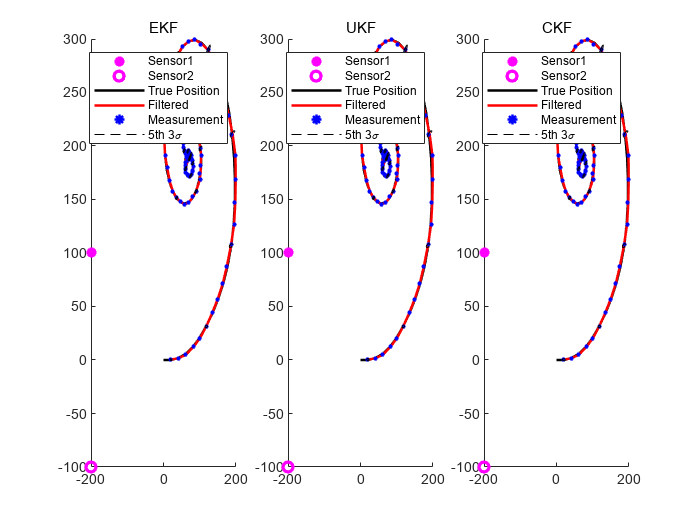


R = diag([sigma_phi1^2, sigma_phi2^2]);
f = @(x) coordinatedTurnMotion(x, T) ;
h = @(x) dualBearingMeasurement(x, s1, s2) ;
% Generate state sequence and measurement sequence
X = genNonLinearStateSequence(x_0, P_0, f, Q, N);
Y = genNonLinearMeasurementSequence(X, h, R);

% Apply the non-linear Kalman filters
[xf_ekf, Pf_ekf, ~, ~] = nonLinearKalmanFilter(Y, x_0, P_0,f, Q, h, R, 'EKF');
[xf_ukf, Pf_ukf, ~, ~] = nonLinearKalmanFilter(Y, x_0, P_0,f, Q, h, R, 'UKF');
[xf_ckf, Pf_ckf, ~, ~] = nonLinearKalmanFilter(Y, x_0, P_0,f, Q, h, R, 'CKF');

figure;
subplot(1,3,1)
hold on;
%Sensor position
plot(s1(1),s1(2),'*m','Linewidth',2);
plot(s2(1),s2(2),'om','Linewidth',2);
% Plot true positions
plot(X(1,:), X(2,:), 'k-', 'LineWidth', 1.5);
%Plot Filters states
plot(xf_ekf(1,:), xf_ekf(2,:), 'r-', 'LineWidth', 1.5);

% Plot Dual bearing measurements
sensorx = (s2(2)-s1(2)+tan(Y(1,:))*s1(1)- tan(Y(2,:))*s2(1))./(tan(Y(1,:))- tan(Y(2,:)));
sensory = s1(2)+tan(Y(1,:)).*(sensorx- s1(1));
scatter(sensorx, sensory, 5,'b*', 'LineWidth',1.5)

for i= 1:5:length(xf_ekf)
        xy = sigmaEllipse2D(xf_ekf(1:2,i), Pf_ekf(1:2,1:2,i), 3, 50);
        plot(xy(1,:),xy(2,:),'--k');
end



legend('Sensor1','Sensor2','True Position','Filtered','Measurement','5th 3\sigma ')
subtitle('EKF')

subplot(1,3,2)
hold on;
%Sensor position
plot(s1(1),s1(2),'*m','Linewidth',2);
plot(s2(1),s2(2),'om','Linewidth',2);
% Plot true positions
plot(X(1,:), X(2,:), 'k-', 'LineWidth', 1.5);
%Plot Filters states
plot(xf_ukf(1,:), xf_ukf(2,:), 'r-', 'LineWidth', 1.5);

% Plot Dual bearing measurements
sensorx = (s2(2)-s1(2)+tan(Y(1,:))*s1(1)- tan(Y(2,:))*s2(1))./(tan(Y(1,:))- tan(Y(2,:)));
sensory = s1(2)+tan(Y(1,:)).*(sensorx- s1(1));
scatter(sensorx, sensory, 5,'b*', 'LineWidth',1.5)

for i= 1:5:length(xf_ukf)
        xy = sigmaEllipse2D(xf_ukf(1:2,i), Pf_ukf(1:2,1:2,i), 3, 50);
        plot(xy(1,:),xy(2,:),'--k');
end



legend('Sensor1','Sensor2','True Position','Filtered','Measurement','5th 3\sigma ')
subtitle('UKF')

subplot(1,3,3)
hold on;
%Sensor position
plot(s1(1),s1(2),'*m','Linewidth',2);
plot(s2(1),s2(2),'om','Linewidth',2);
% Plot true positions
plot(X(1,:), X(2,:), 'k-', 'LineWidth', 1.5);
%Plot Filters states
plot(xf_ckf(1,:), xf_ckf(2,:), 'r-', 'LineWidth', 1.5);

% Plot Dual bearing measurements
sensorx = (s2(2)-s1(2)+tan(Y(1,:))*s1(1)- tan(Y(2,:))*s2(1))./(tan(Y(1,:))- tan(Y(2,:)));
sensory = s1(2)+tan(Y(1,:)).*(sensorx- s1(1));
scatter(sensorx, sensory, 5,'b*', 'LineWidth',1.5)

for i= 1:5:length(xf_ckf)
        xy = sigmaEllipse2D(xf_ckf(1:2,i), Pf_ckf(1:2,1:2,i), 3, 50);
        plot(xy(1,:),xy(2,:),'--k');
end




legend('Sensor1','Sensor2','True Position','Filtered','Measurement','5th 3\sigma ')
subtitle('CKF')